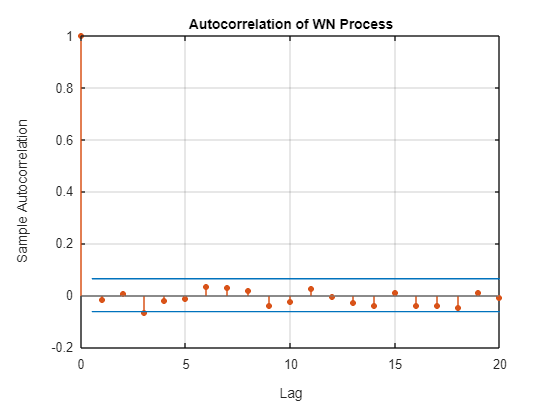

clear all
clc
rng(514); 
% Number of observations
T = 1000;

%1
%a
% Generate white noise
epsilon = randn(T,1);
y1 = epsilon;

% Plot the Autocorrelation Function (ACF)
figure;
autocorr(y1, 'NumLags', 20);
title('Autocorrelation of WN Process');

% Estimate an MA(2) Model
Mdl = arima(0,0,2);
EstMdl = estimate(Mdl, y1);

 
    ARIMA(0,0,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant      0.03991      0.030641          1.3025         0.19273
    MA{1}       -0.015304      0.033055        -0.46298         0.64338
    MA{2}       0.0042101      0.031332         0.13437         0.89311
    Variance      0.95716      0.043522          21.993     3.3851e-107



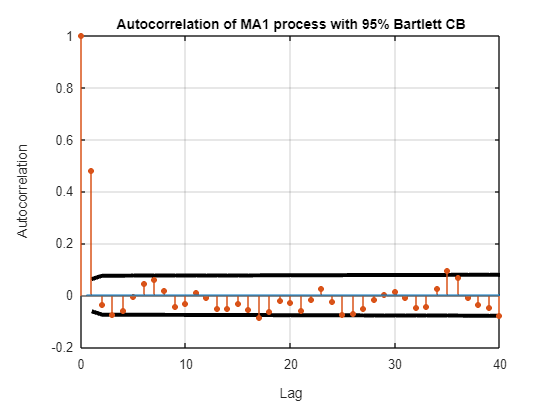

%b
% Generate MA(1) process using the same white noise from part (a)
y2 = epsilon + 0.8 * [0; epsilon(1:end-1)]; % MA(1): y_t = ε_t + 0.8ε_t-1
% Set number of lags
q = 40;  % Number of lags in ACF plot

% Compute ACF
acf_values_b = autocorr(y2, 'NumLags', q); % Autocorrelations for lags 0,1,...,q

% Compute Bartlett’s Confidence Bands
whh_b = 2 * cumsum(acf_values_b .* acf_values_b) - 1;
ci_bart_a(:,2) = 1.96 * sqrt(whh_b / T); % Upper interval (z_{a/2}σ, a=5%)
ci_bart_a(:,1) = -1.96 * sqrt(whh_b / T); % Lower interval (-z_{a/2}σ, a=5%)

% Plot ACF with Bartlett Confidence Bands
figure;
plot(1:q, ci_bart_a(1:q,:), 'k', 'LineWidth', 3); % Plot confidence bands
hold on;
autocorr(y2, 'NumLags', q, 'NumSTD', 0); % Plot ACF without default confidence bands
title('Autocorrelation of MA1 process with 95% Bartlett CB');
xlabel('Lag');
ylabel('Autocorrelation');
grid on;


% Still estimating MA(2), even though data is MA(1)
Mdl2 = arima(0,0,2); % MA(2) model (as required)
EstMdl2 = estimate(Mdl2, y2);

 
    ARIMA(0,0,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant     0.069094      0.055731         1.2398          0.21506
    MA{1}         0.78558      0.033076         23.751      1.0843e-124
    MA{2}       0.0099435      0.032945        0.30182          0.76279
    Variance      0.95619      0.043654         21.904       2.376e-106



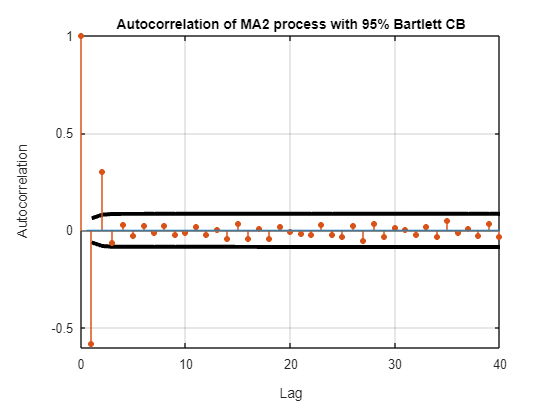

%c
% Generate MA(2) process using the same white noise from part (a)
y3 = epsilon - 0.6 * [0; epsilon(1:end-1)] + 0.4 * [0; 0; epsilon(1:end-2)]; 
% MA(2): y_t = ε_t - 0.6ε_t-1 + 0.4ε_t-2

% Set number of lags
q = 40;  % Number of lags in ACF plot

% Compute ACF
acf_values_c = autocorr(y3, 'NumLags', q); % Autocorrelations for lags 0,1,...,q

% Compute Bartlett’s Confidence Bands
whh_c = 2 * cumsum(acf_values_c .* acf_values_c) - 1;
ci_bart_b(:,2) = 1.96 * sqrt(whh_c / T); % Upper interval (z_{a/2}σ, a=5%)
ci_bart_b(:,1) = -1.96 * sqrt(whh_c / T); % Lower interval (-z_{a/2}σ, a=5%)

% Plot ACF with Bartlett Confidence Bands
figure;
plot(1:q, ci_bart_b(1:q,:), 'k', 'LineWidth', 3); % Plot confidence bands
hold on;
autocorr(y3, 'NumLags', q, 'NumSTD', 0); % Plot ACF without default confidence bands
title('Autocorrelation of MA2 process with 95% Bartlett CB');
xlabel('Lag');
ylabel('Autocorrelation');
grid on;


% Estimate an MA(2) Model
Mdl3 = arima(0,0,2);
EstMdl3 = estimate(Mdl3, y3);

 
    ARIMA(0,0,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.032307      0.024203         1.3348          0.18193
    MA{1}       -0.59122      0.030214        -19.567       2.9287e-85
    MA{2}        0.37308      0.030214         12.348       5.0136e-35
    Variance      0.9565      0.043465         22.006      2.4964e-107



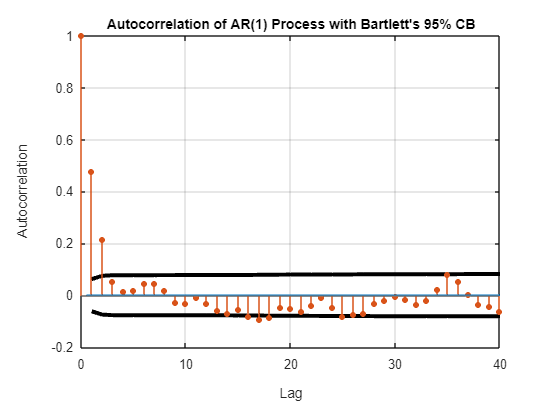

% d: AR(1) Process (but estimating MA(2))
% Generate AR(1) process using the same white noise from part (a)
y4 = zeros(T,1); % Initialize AR(1) series
phi = 0.5; % AR(1) coefficient

for t = 2:T
    y4(t) = phi * y4(t-1) + epsilon(t); % AR(1): y_t = 0.5 y_t-1 + ε_t
end

% Set number of lags
q = 40; % Number of lags in ACF plot

% Compute ACF
acf_values_d = autocorr(y4, 'NumLags', q); % Autocorrelations for lags 0,1,...,q

% Compute Bartlett’s Confidence Bands
whh_d = 2 * cumsum(acf_values_d .* acf_values_d) - 1;
ci_bart_d(:,2) = 1.96 * sqrt(whh_d / T); % Upper interval (z_{a/2}σ, a=5%)
ci_bart_d(:,1) = -1.96 * sqrt(whh_d / T); % Lower interval (-z_{a/2}σ, a=5%)

% Plot ACF with Bartlett Confidence Bands
figure;
plot(1:q, ci_bart_d(1:q,:), 'k', 'LineWidth', 3); % Plot confidence bands
hold on;
autocorr(y4, 'NumLags', q, 'NumSTD', 0); % Plot ACF without default confidence bands
title('Autocorrelation of AR(1) Process with Bartlett''s 95% CB');
xlabel('Lag');
ylabel('Autocorrelation');
grid on;


% Still estimating MA(2), even though data is AR(1)
Mdl4 = arima(0,0,2); % MA(2) model (as required)
EstMdl4 = estimate(Mdl4, y4);

 
    ARIMA(0,0,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant    0.079595      0.052315         1.5215          0.12814
    MA{1}        0.47179      0.032816         14.377       7.2615e-47
    MA{2}        0.21641      0.030914         7.0005       2.5513e-12
    Variance      0.9561      0.043833         21.813      1.7613e-105



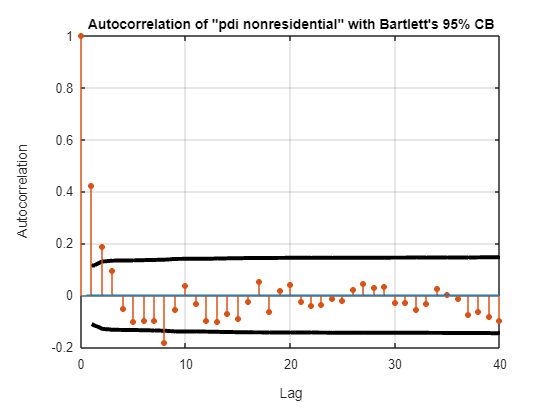

%2
data = readtable('realgdpgrowth.xlsx'); 
pdi = data.pdi_nonresidential; % Extract "pdi nonresidential" series

% Set number of lags
q = 40;  % Number of lags for ACF plot
T = length(pdi); % Length of the time series

% Compute ACF
acf_values_q2 = autocorr(pdi, 'NumLags', q); % Autocorrelations for lags 0,1,...,q


% Compute Bartlett’s Confidence Bands
whh_q2 = 2 * cumsum(acf_values_q2 .* acf_values_q2) - 1;
ci_bart_q2(:,2) = 1.96 * sqrt(whh_q2 / T); % Upper confidence band (z_{a/2}σ, a=5%)
ci_bart_q2(:,1) = -1.96 * sqrt(whh_q2 / T); % Lower confidence band (-z_{a/2}σ, a=5%)

% Plot ACF with Bartlett Confidence Bands
figure;
plot(1:q, ci_bart_q2(1:q,:), 'k', 'LineWidth', 3); % Plot confidence bands
hold on;
autocorr(pdi, 'NumLags', q, 'NumSTD', 0); % Plot ACF without default confidence bands
title('Autocorrelation of "pdi nonresidential" with Bartlett''s 95% CB');
xlabel('Lag');
ylabel('Autocorrelation');
grid on;



Mdlq21 = arima(0,0,1);
Mdlq22 = arima(0,0,2);
Mdlq23 = arima(0,0,3);
Mdlq24 = arima(0,0,4);

EstMdlq2a = estimate(Mdlq21, pdi);

 
    ARIMA(0,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     4.8018       0.73853         6.5018      7.9375e-11
    MA{1}       0.38556      0.041567         9.2757      1.7647e-20
    Variance     78.184        3.9279         19.905      3.6871e-88



EstMdlq2b = estimate(Mdlq22, pdi);

 
    ARIMA(0,0,2) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     4.7914       0.80431         5.9572       2.566e-09
    MA{1}       0.40445      0.040495         9.9876      1.7264e-23
    MA{2}       0.12126      0.054329          2.232        0.025615
    Variance     76.972        3.9169         19.651      5.6662e-86



EstMdlq2c = estimate(Mdlq23, pdi);

 
    ARIMA(0,0,3) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant      4.744       0.93286         5.0854      3.6679e-07
    MA{1}        0.4227      0.041339         10.225      1.5272e-24
    MA{2}       0.19345      0.058124         3.3282       0.0008742
    MA{3}       0.16402      0.059569         2.7534       0.0058975
    Variance     75.237        3.8561         19.511      8.8561e-85



EstMdlq2d = estimate(Mdlq24, pdi);

 
    ARIMA(0,0,4) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant       4.7432       0.93201          5.0892     3.5959e-07
    MA{1}         0.41918      0.041406          10.124     4.3386e-24
    MA{2}         0.19047      0.058519          3.2549      0.0011345
    MA{3}         0.16074      0.060613           2.652      0.0080026
    MA{4}       -0.018147       0.05905        -0.30732         0.7586
    Variance       75.218        4.1004          18.344     3.6827e-75

